clear;
close all;
clc;

addpath('GSH\Tools\')

addpath('GSH\Data\MercuryCrust\')

addpath('GSH\Data\MercuryGrav\')


aa=10;

G = 6.6743e-11;
R_ref = 2440e3;
M_mercury = 0.330103e24;
g_ref = G*M_mercury/R_ref^2

g_ref = 3.7006

rho_crust = 3103.892

rho_crust = 3.1039e+03

% rho_crust = 2500
rho_mantle = 3239.353

rho_mantle = 3.2394e+03

% Create lat/lon grid
resolution = 1;
latLimT = [-90+(1/resolution/2) 90-(1/resolution/2) 1/resolution];
lonLimT = [1/resolution/2  360-(1/resolution/2) 1/resolution];
% lonLimT = [-180+1/resolution/2  180-(1/resolution/2) 1/resolution];

lonT = lonLimT(1):lonLimT(3):lonLimT(2);
latT = fliplr(latLimT(1):latLimT(3):latLimT(2));
LonT = repmat(lonT,length(latT),1);
LatT = repmat(latT',1,length(lonT));

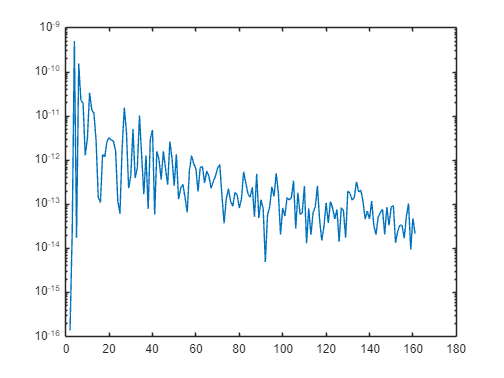

% Read Gravity Spherical Harmonics
SC_data = readmatrix('cleaned_gsh.csv', OutputType='double');

L = max(SC_data(:,1));
clm = SC_data(:, 1:4);
clm = [0 0 0 0; clm];

[n, DV] = degreeVariance(clm);
figure
semilogy(DV)



% Convert to /S|C\ Triangle format
sc = clm2sc(clm);

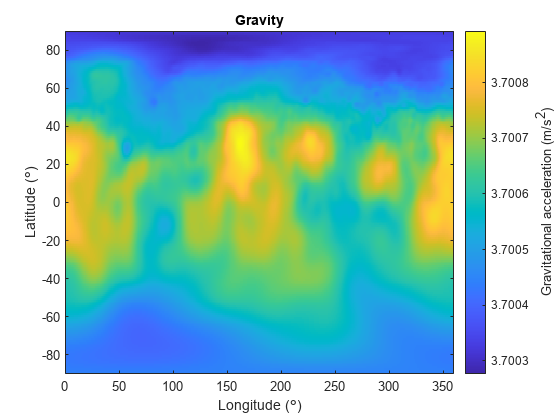

% Plot gravitational potential
gravity_map_norm = GSHS(sc, lonT, 90-latT, 160);

gravity_map = (1+gravity_map_norm) * g_ref;

gravity_anomaly_map = gravity_map_norm * g_ref;

% V = model_SH_analysis()

figure
imagesc(lonT,latT,gravity_map);cc=colorbar;
title('Gravity')
xlabel('Longitude (\circ)','Fontsize',aa)
ylabel('Latitude (\circ)','Fontsize',aa)
ylabel(cc,'Gravitational acceleration (m/s^2)','Fontsize',aa)
set(gca,'YDir','normal','Fontsize',aa)

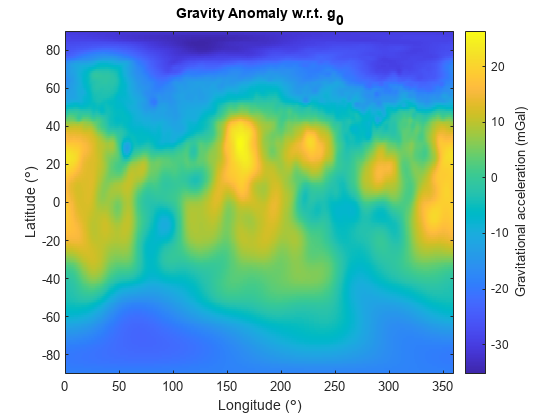


% figure
% axesm('mollweid', 'Frame', 'off', 'Grid', 'off', 'MeridianLabel', 'off', 'ParallelLabel', 'off')
% % setm(gca, 'MLabelParallel', 3)
% geoshow(LatT, LonT, gravity_anomaly_map, 'DisplayType', 'surface')
% title('Gravity Anomaly w.r.t. Geoid')
% colorbar;
% xlabel('Longitude (\circ)')
% ylabel('Latitude (\circ)')
% ylabel(cc,'Gravitational acceleration (m/s^2)')
% set(gca, 'YDir', 'normal')

figure
imagesc(lonT,latT,gravity_anomaly_map*1e5);cc=colorbar;
title('Gravity Anomaly w.r.t. g_0')
xlabel('Longitude (\circ)','Fontsize',aa)
ylabel('Latitude (\circ)','Fontsize',aa)
ylabel(cc,'Gravitational acceleration (mGal)','Fontsize',aa)
set(gca,'YDir','normal','Fontsize',aa)


% light
% material(0.6*[1 1 1])
% axis normal
% view(3)


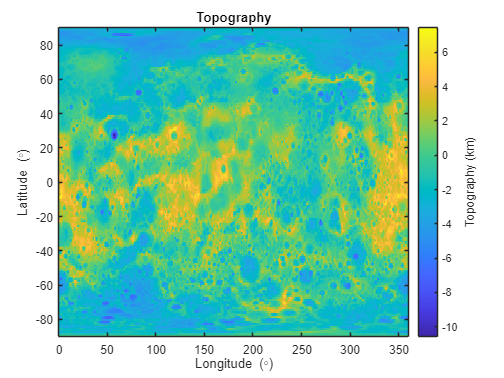

% Load topography
filename = 'GSH\Data\MercuryTopo\mercurytopo.tif';
% f = fopen(filename,'r','ieee-be');
% topo_map = fread(f,[360*250 Inf],'int16')';
% fclose(f); 

topo_map = imread(filename);

resized_topo_map = imresize(topo_map, [size(gravity_map, 1), size(gravity_map, 2)]);
resized_topo_map = double(resized_topo_map);

topo_zero = zeros(size(resized_topo_map));
gmtzero = matrix2gmt(topo_zero, LonT, LatT);
filename = 'GSH\Data\crust_bd_zero.gmt';
writematrix(gmtzero, filename, 'FileType', 'text');

% Plot topography
figure
imagesc(lonT,latT,resized_topo_map./1e3);cc=colorbar;
title('Topography')
xlabel('Longitude (\circ)','Fontsize',aa)
ylabel('Latitude (\circ)','Fontsize',aa)
ylabel(cc,'Topography (km)','Fontsize',aa)
set(gca,'YDir','normal','Fontsize',aa)

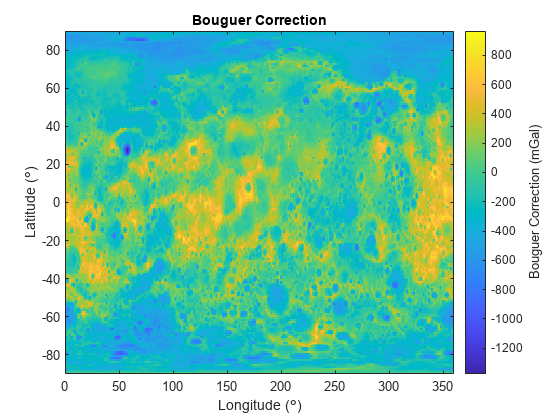

% Calculate bouguer anomaly
free_air_correction = 2*gravity_map.*resized_topo_map/R_ref;
free_air_gravity_anomaly = gravity_anomaly_map + free_air_correction;

bouguer_correction = 2*pi*G*rho_crust*resized_topo_map;
bouguer_anomaly=free_air_gravity_anomaly-bouguer_correction;
% bouguer_anomaly = gravity_anomaly_map + bouguer_correction;

% Plot Bouguer Correction
figure
imagesc(lonT,latT,bouguer_correction*1e5);cc=colorbar;
title('Bouguer Correction')
xlabel('Longitude (\circ)','Fontsize',aa)
ylabel('Latitude (\circ)','Fontsize',aa)
ylabel(cc,'Bouguer Correction (mGal)','Fontsize',aa)
set(gca,'YDir','normal','Fontsize',aa)

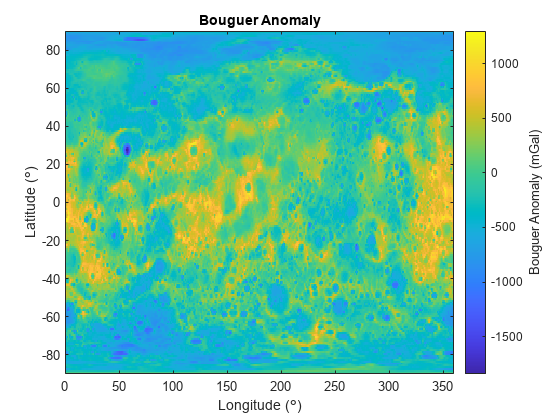


% Plot Bouguer Anomaly
figure
imagesc(lonT,latT,bouguer_anomaly*1e5);cc=colorbar;
title('Bouguer Anomaly')
xlabel('Longitude (\circ)','Fontsize',aa)
ylabel('Latitude (\circ)','Fontsize',aa)
ylabel(cc,'Bouguer Anomaly (mGal)','Fontsize',aa)
set(gca,'YDir','normal','Fontsize',aa)

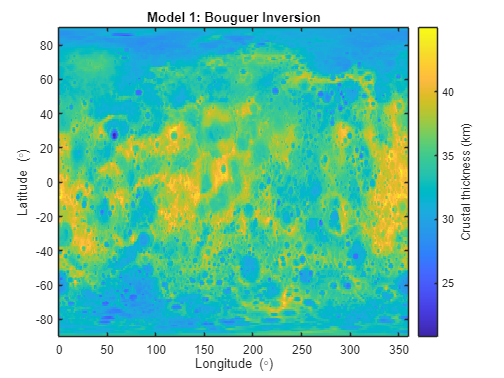

% Model 1: Bouguer Inversion
D_ref = 35e3; % km reference crustal thickness

deltaR1 = bouguer_anomaly/(2*pi*G*rho_crust);

crustal_thickness_1 = (D_ref + deltaR1)./1e3;

figure
imagesc(lonT, latT,crustal_thickness_1); cc=colorbar;
title('Model 1: Bouguer Inversion')
xlabel('Longitude (\circ)','Fontsize',aa)
ylabel('Latitude (\circ)','Fontsize',aa)
ylabel(cc,'Crustal thickness (km)','Fontsize',aa)
set(gca,'YDir','normal','Fontsize',aa)


gmt1 = matrix2gmt(-crustal_thickness_1, LonT, LatT);
filename = 'GSH\Data\Model1\crust_lower_bd_1.gmt';
writematrix(gmt1, filename, 'FileType', 'text');

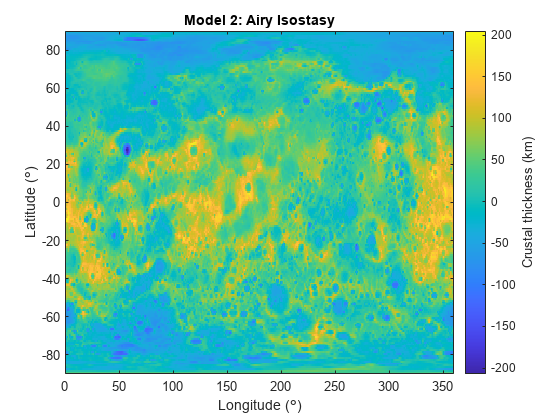

% Model 2: Airy Isostasy
deltaR2 = resized_topo_map*rho_crust/(rho_mantle-rho_crust);
crustal_thickness_2 = (resized_topo_map+D_ref + deltaR2) / 1e3; % Convert to km

figure
imagesc(lonT, latT, crustal_thickness_2); cc=colorbar;
title('Model 2: Airy Isostasy')
xlabel('Longitude (\circ)','Fontsize',aa)
ylabel('Latitude (\circ)','Fontsize',aa)
ylabel(cc,'Crustal thickness (km)','Fontsize',aa)
set(gca,'YDir','normal','Fontsize',aa)


% crust_lower_boundary_depth = resized_topo_map/1e3-crustal_thickness;
% gmt2 = matrix2gmt(crust_lower_boundary_depth, LonT, LatT);

gmt2 = matrix2gmt(-crustal_thickness_2, LonT, LatT);
filename = 'GSH\Data\Model2\crust_lower_bd_2.gmt';
writematrix(gmt2, filename, 'FileType', 'text');
% Model_2_Airy;
% V_model = segment_2layer_model(resized_topo_map/1e3, crust_lower_boundary_depth, -150e3, rho_crust, rho_mantle, 5000, Model);

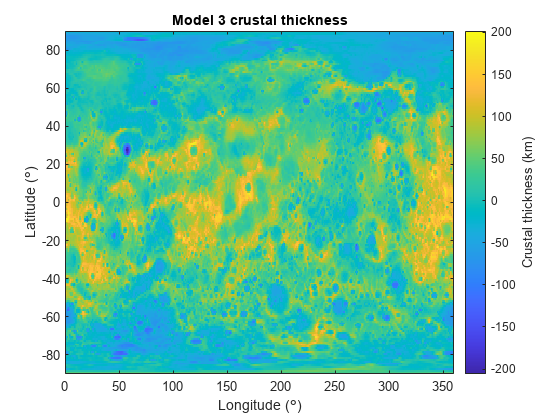

% Flexure
Te_ref = 31e3; % Reference elastic thickness (James et al)
sc_flex = run_model_3(resized_topo_map, Te_ref, g_ref, R_ref);
mapf = GSHS(sc_flex,lonT,90-latT,160);

crustal_thickness_3 = crustal_thickness_2 - mapf./1e3;
gmt3 = matrix2gmt(-crustal_thickness_3, LonT, LatT);
filename = 'GSH\Data\Model3\crust_lower_bd_3.gmt';
writematrix(gmt2, filename, 'FileType', 'text');

figure
imagesc(lonT,latT,crustal_thickness_3);cc=colorbar;
title("Model 3 crustal thickness")
xlabel('Longitude (\circ)','Fontsize',aa)
ylabel('Latitude (\circ)','Fontsize',aa)
ylabel(cc,'Crustal thickness (km)','Fontsize',aa)
set(gca,'YDir','normal','Fontsize',aa)

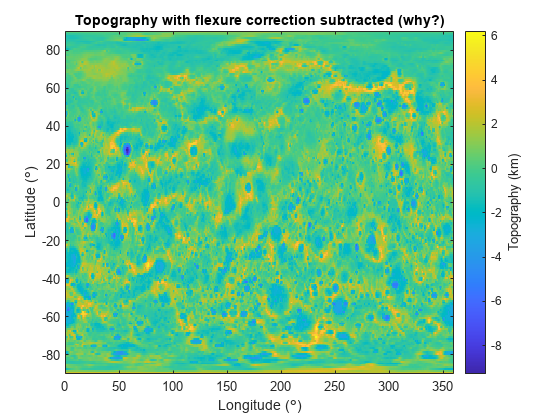



figure
imagesc(lonT,latT,(resized_topo_map-mapf)./1e3);cc=colorbar;
colormap("parula");
title("Topography with flexure correction subtracted (why?)")
xlabel('Longitude (\circ)','Fontsize',aa)
ylabel('Latitude (\circ)','Fontsize',aa)
ylabel(cc,'Topography (km)','Fontsize',aa)
set(gca,'YDir','normal','Fontsize',aa)

function sc_flex = run_model_3(resized_topo_map, Te, g_ref, R_ref)
    cs3 = GSHA(resized_topo_map, 160);
    sc3 =  cs2sc(cs3);
    n = 1:size(sc3,1);
    
    D = 200e9*(Te)^3/(12*(1-0.5^2));
    PHI = (1 + D/(500*g_ref).*(2.*(n+1)./(2*R_ref)).^4).^(-1);
    
    sc_flex = zeros(size(sc3));
    
    for m = 1:size(sc3,2)
        sc_flex(:,m) = sc3(:,m).*PHI';
    end
end